filename = dir(fullfile(pwd,'*C001*'))

filename = struct with fields:
       name: 'WT_5_C001.tif'
     folder: 'D:\Dropbox\NUS_PhD\PhD_Project_LYP_Lab\Experimental_Log\Combined Data\VASP WBP2 interaction\070619 VASP WBP2 Localisation n2\Export\WT VASP\WT_5.tif.frames'
       date: '07-Jun-2019 12:05:06'
      bytes: 1049028
      isdir: 0
    datenum: 7.3758e+05


WBP2 = imread(filename.name);
filename = dir(fullfile(pwd,'*C002*'))

filename = struct with fields:
       name: 'WT_5_C002.tif'
     folder: 'D:\Dropbox\NUS_PhD\PhD_Project_LYP_Lab\Experimental_Log\Combined Data\VASP WBP2 interaction\070619 VASP WBP2 Localisation n2\Export\WT VASP\WT_5.tif.frames'
       date: '07-Jun-2019 12:05:06'
      bytes: 1049028
      isdir: 0
    datenum: 7.3758e+05


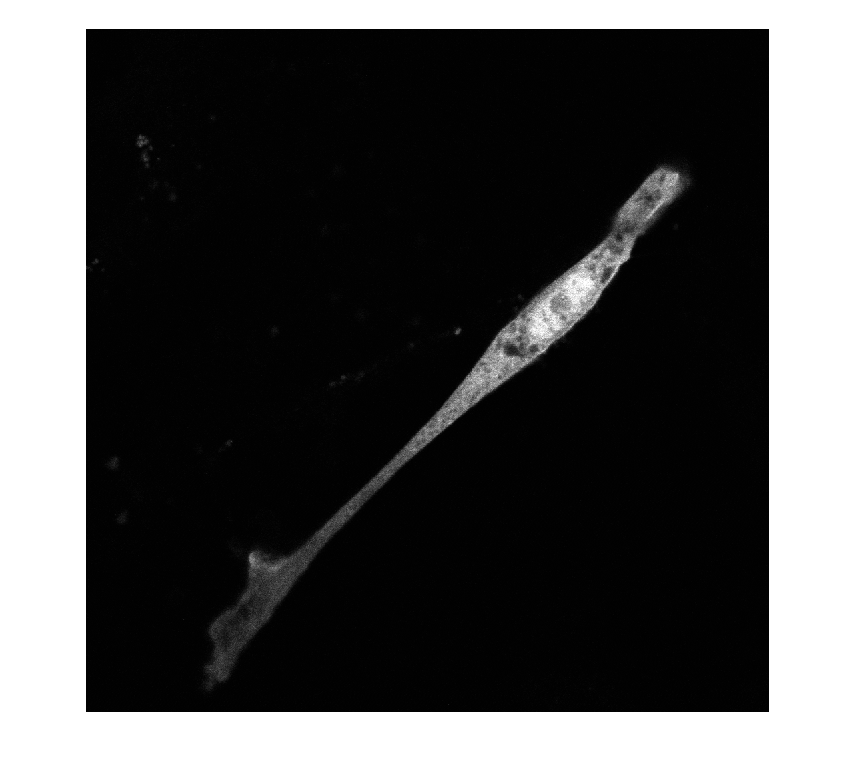

VASP = imread(filename.name);
figure
imshow(WBP2)

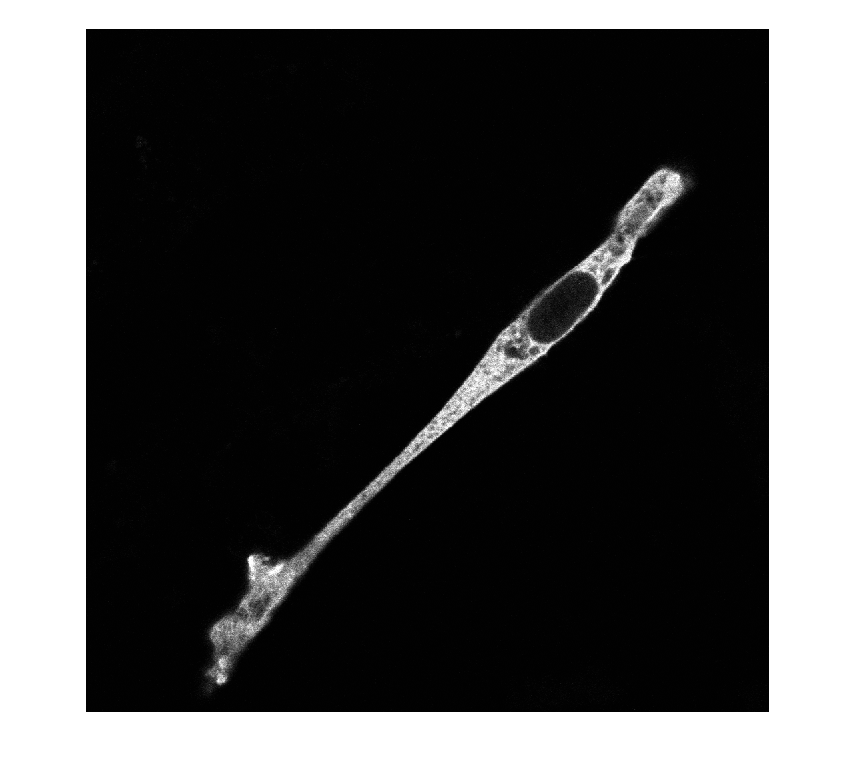

figure
imshow(VASP)

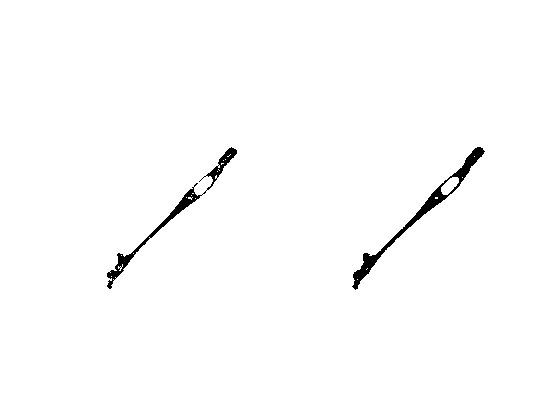

VASPcomp  = imcomplement(VASP);
VASPbw = imbinarize(VASPcomp);
figure
subplot(1,2,1);
imshow(VASPbw)
se = strel('disk',2);
VASPbw_ero = imerode(VASPbw,se);
subplot(1,2,2)
imshow(VASPbw_ero);

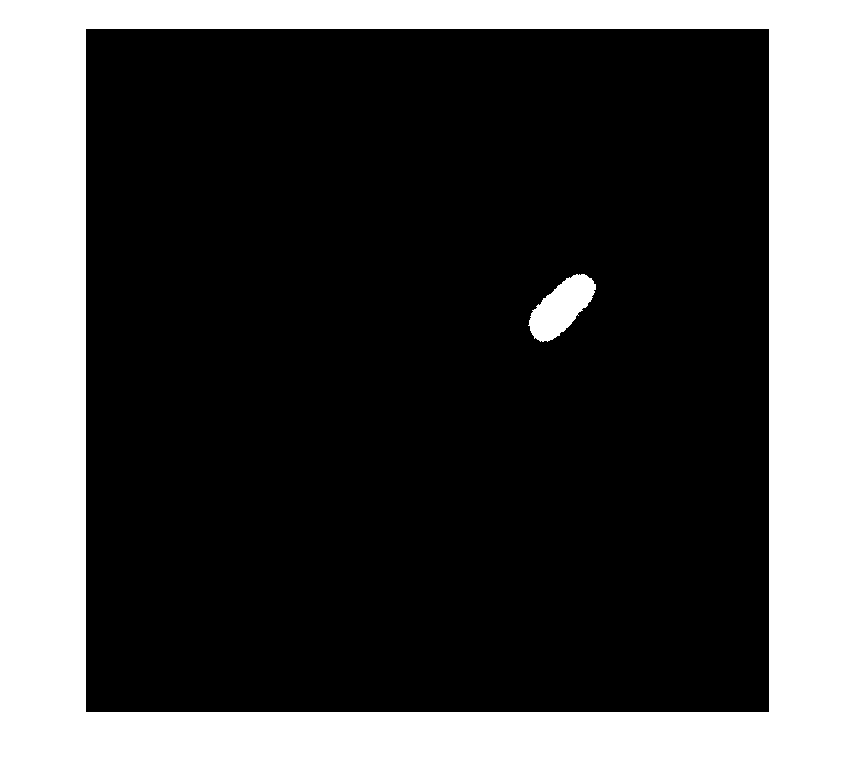

nuc = bwareafilt(VASPbw_ero,2) - bwareafilt(VASPbw_ero,1);
nuc = imfill(nuc,'holes');
total = bwareafilt(VASPbw_ero,1);
total = imcomplement(total);
total = bwareafilt(total,1);
cyto = total - nuc;
figure
imshow(nuc)

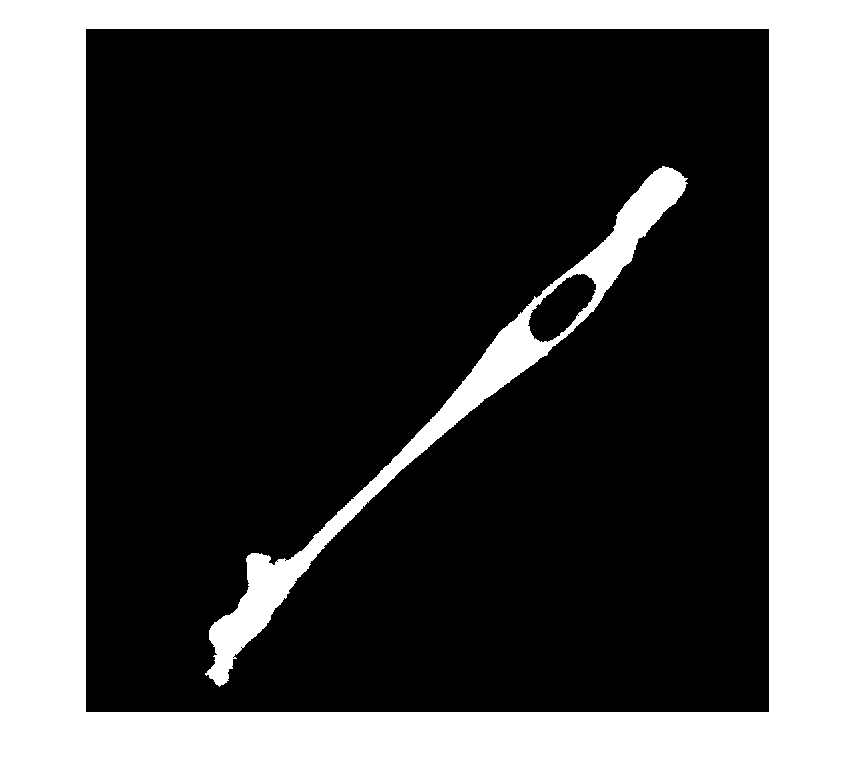

figure
imshow(cyto)

cyto = uint8(cyto);
nuc = uint8(nuc);
total = uint8(total);
C_WBP2 = cyto .* WBP2;
C_WBP2(cyto == 0) = [];
C_WBP2 = double(C_WBP2);

N_WBP2 = nuc .* WBP2;
N_WBP2(nuc == 0) = [];
N_WBP2 = double(N_WBP2);

T_WBP2 = total .* WBP2;
T_WBP2(total == 0) = [];
T_WBP2 = double(T_WBP2);

C_VASP = cyto .* VASP;
C_VASP(cyto == 0) = [];
C_VASP = double(C_VASP);

N_VASP = nuc .* VASP;
N_VASP(nuc == 0) = [];
N_VASP = double(N_VASP);

T_VASP = total .* VASP;
T_VASP(total == 0) = [];
T_VASP = double(T_VASP);

%Colocalisation analysis with PDM (product of the difference from the mean)
WBP2_max = max(max(T_WBP2));
VASP_max = max(max(T_VASP));

WBP2_mean = mean(mean(T_WBP2))/WBP2_max;
VASP_mean = mean(mean(T_VASP))/VASP_max;

VASP_cell = total .* VASP;
WBP2_cell = total .* WBP2;

VASP_cell = double(VASP_cell);
WBP2_cell = double(WBP2_cell);

VASP_cell = VASP_cell./VASP_max;
WBP2_cell = WBP2_cell./WBP2_max;

WBP2_diff = WBP2_cell - WBP2_mean;
VASP_diff = VASP_cell - VASP_mean;

PDM = WBP2_diff .* VASP_diff;

PDM(total==0) = NaN;

figure
imshow(PDM,[-0.25,0.25])

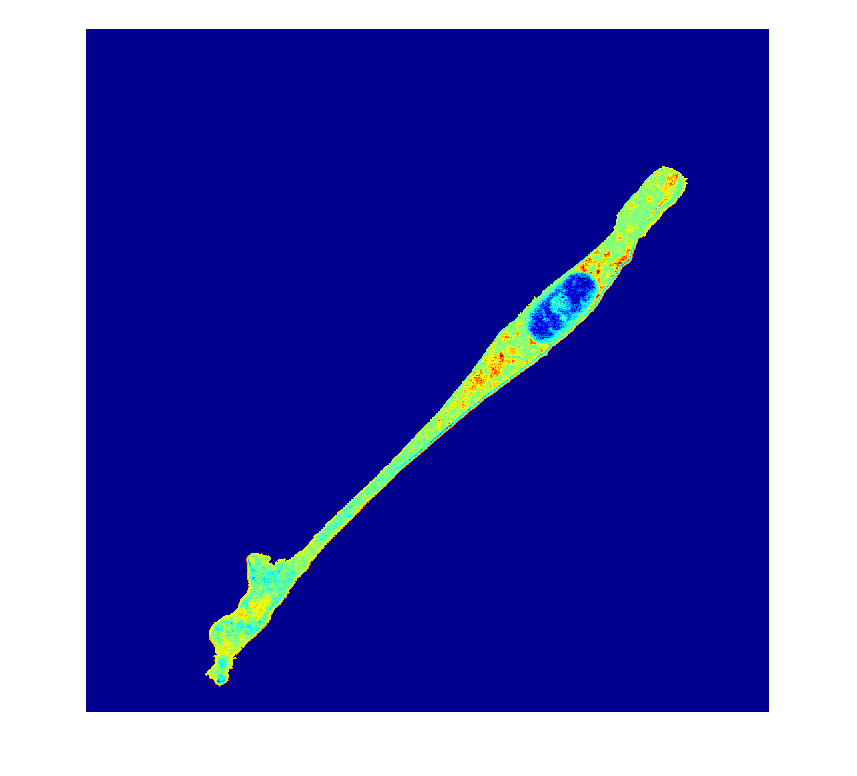

colormap(gca,'jet')

%Calculate ICQ
nuc = nuc == 1;
cyto = cyto ==1;
pos_PDM = PDM > 0;
T_ICQ = sum(sum(pos_PDM))/sum(sum(total)) - 0.5

T_ICQ = 0.0548

N_ICQ = pos_PDM .* nuc;
N_ICQ = sum(sum(N_ICQ))/sum(sum(nuc)) - 0.5

N_ICQ = -0.4970

C_ICQ = pos_PDM .* cyto;
C_ICQ = sum(sum(C_ICQ))/sum(sum(cyto)) - 0.5

C_ICQ = 0.1317


ICQ = [T_ICQ N_ICQ C_ICQ]

ICQ =     0.0548   -0.4970    0.1317


clipboard('copy',ICQ)
imwrite(PDM,'output.tif')

CR = corrcoef(C_WBP2,C_VASP);
NR = corrcoef(N_WBP2,N_VASP);
TR = corrcoef(T_WBP2,T_VASP);

output(1,1) = TR(1,2);
output(1,2) = NR(1,2);
output(1,3) = CR(1,2);